## **Esercizio 1**

clear variables; close all; clc;

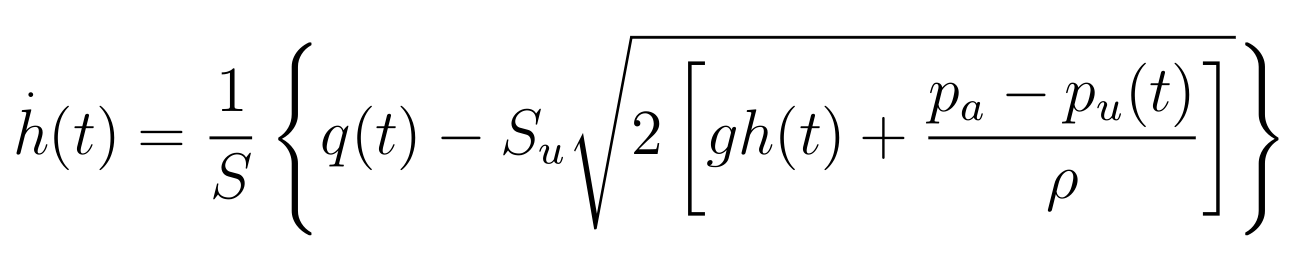

#### Equilibrio:

% pressione liquido in ingresso al serbatoio [Pa] = [kg m^-1 s^-2]
p_u = 0.9e5;

% altezza liquido nel serbatoio [m]
h = 0.2;

#### **Parametri del sistema:**

% accelerazione di gravità [m s^-2]
g = 9.8;

% pressione atmosferica [Pa] = [kg m^-1 s^-2]
p_a = 1e5;

% densità di massa liquido nel serbatoio [kg m^-3]
rho = 1000;

% sezione per il liquido in ingresso al serbatoio [m^2]
S_u = 8.7e-4;

% sezione del serbatoio [m^2]
S = 0.2;

#### **Parametri del regolatore:**

% guadagno del regolare [m^3 s^-1 V^-1]
mu = 0.005;

% costante di tempo polo del regolatore [s]
T1 = 0.1;

% costante di tempo polo del regolatore [s]
T2 = 2;

### **1) Punto di equilibrio**

** Si determini, per d = 0, l’ingresso costante che garantisce all’equilibrio h = 0.2m.**

d = 0

d = 0

q = S_u * sqrt(2*(g*h+((p_a-p_u)/rho)))

q = 0.0043

w = q + d

w = 0.0043

### **2) Linearizzazione sistema all'equilibrio**

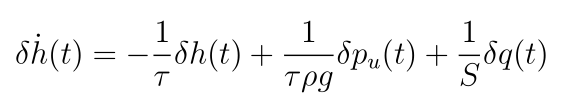

tau = (S*sqrt(2*(g*h+(p_a-p_u)/rho))) / (S_u*g)

tau = 114.7269

dhh = -1/tau

dhh = -0.0087

dhp_u = 1/(tau*rho*g)

dhp_u = 8.8942e-07

dhq = 1/S

dhq = 5

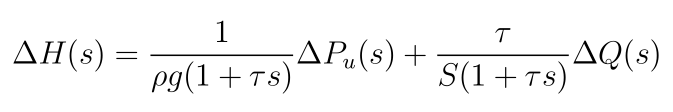

s = tf('s');
G = tau/S * 1/(1+tau*s)


G =
 
     573.6
  -----------
  114.7 s + 1
 
Continuous-time transfer function.



M = 1/(rho*g) * 1/(1+tau*s)


M =
 
   0.000102
  -----------
  114.7 s + 1
 
Continuous-time transfer function.



### **3) Disegnare schema a blocchi**

**Si disegni lo schema a blocchi del sistema (linearizzato) con ingressi δu (variazione di u) e δp u e uscita δh.**

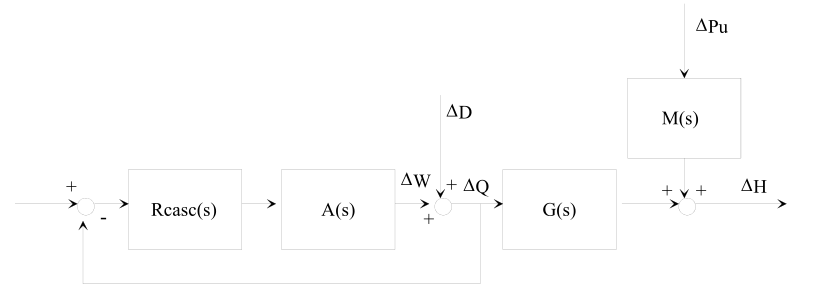

### **4) Progettazione regolatore in cascata - Anello interno**

**Supponendo che la portata d’ingresso effettiva sia misurabile, si progetti uno schema di controllo in cascata che garantisca un’attenuazione di almeno 20dB del disturbo d, il cui spettro ha banda massima 0.1rad/s, su q.**

A = mu/((1+T1*s)*(1+T2*s))


A =
 
         0.005
  -------------------
  0.2 s^2 + 2.1 s + 1
 
Continuous-time transfer function.



mu_R = 10/mu

mu_R = 2000

R = mu_R

R = 2000

L = R*A


L =
 
          10
  -------------------
  0.2 s^2 + 2.1 s + 1
 
Continuous-time transfer function.



F = minreal(L/(1+L))


F =
 
         50
  -----------------
  s^2 + 10.5 s + 55
 
Continuous-time transfer function.



banda_anello_interno = max(abs(real(pole(F))))

banda_anello_interno = 5.2500

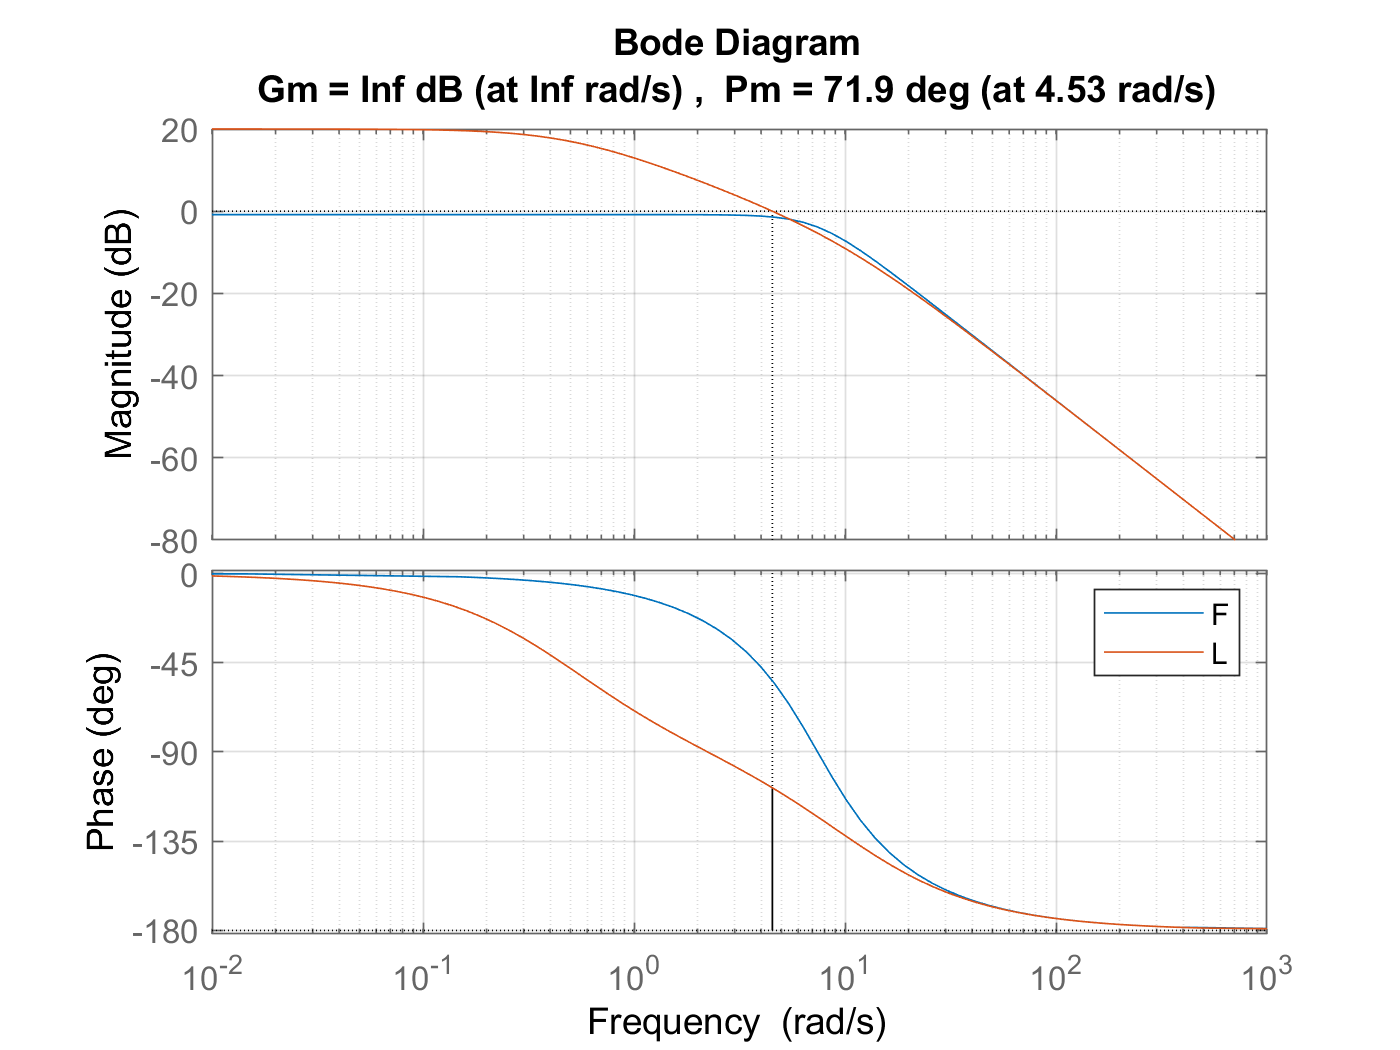

figure; hold on; bode(F); margin(L); grid on; legend;

### **5) Progettazione regolatore in cascata - Anello esterno**

**Si progetti un regolatore PI in grado di garantire che la risposta del sistema retroazionato a fronte di uno scalino di ingresso arrivi al 99% del valore di regime in circa 200s.**

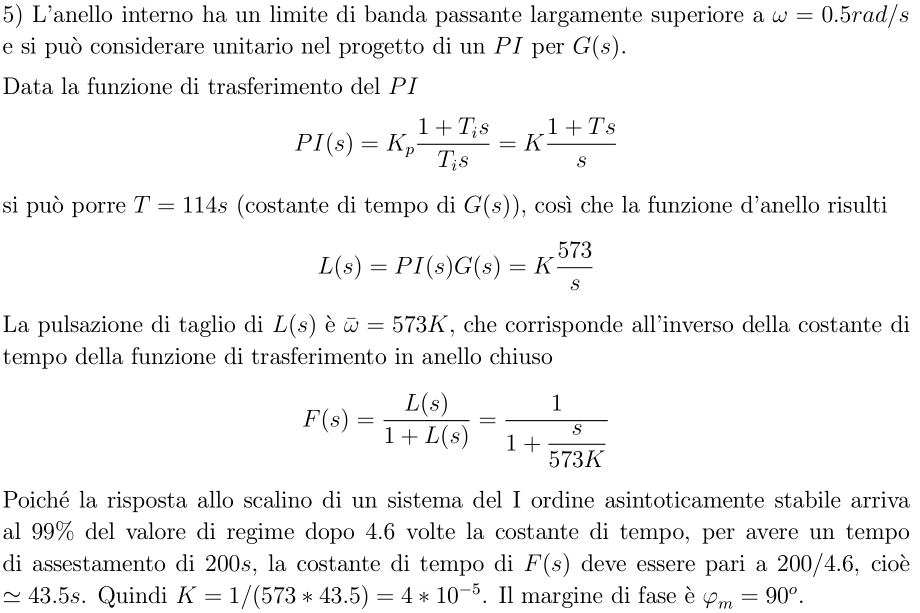

mu_R2 = 4.6/(dcgain(G)*200)

mu_R2 = 4.0095e-05

tau_R2 = tau;
R2 = mu_R2 * (1+tau_R2*s)/s;
L2 = minreal(R2*G)


L2 =
 
  0.023
  -----
    s
 
Continuous-time transfer function.



F2 = minreal(L2/(1+L2))


F2 =
 
    0.023
  ---------
  s + 0.023
 
Continuous-time transfer function.



banda_anello_esterno = max(abs(real(pole(F2))))

banda_anello_esterno = 0.0230

verifica_anelli_disaccopiati = banda_anello_interno >= banda_anello_esterno * 10

verifica_anelli_disaccopiati = logical
   1


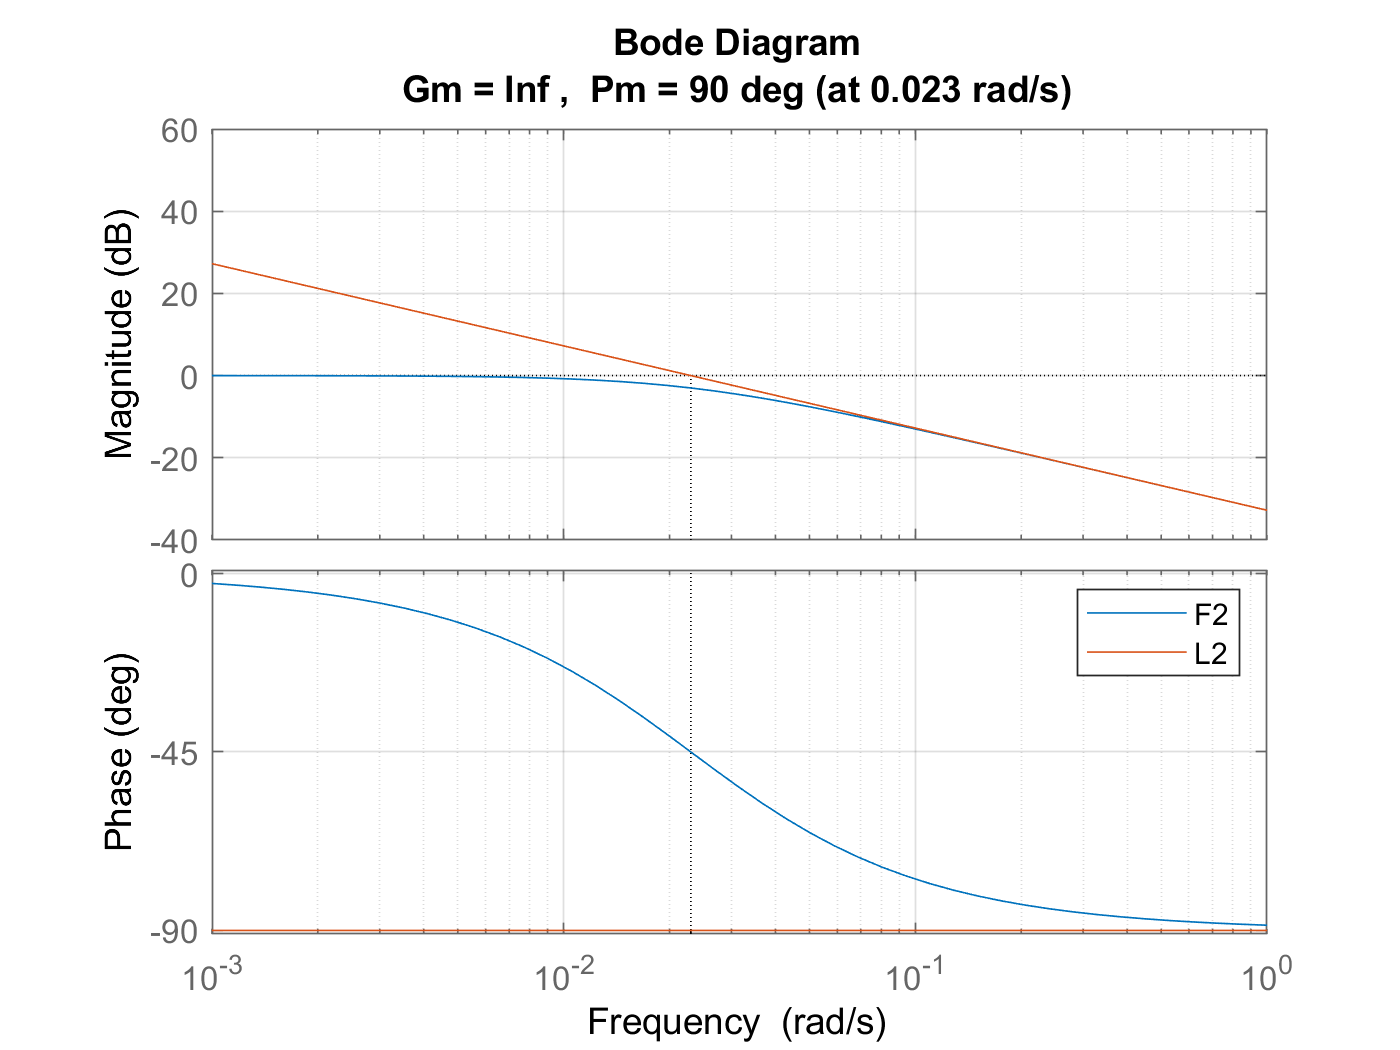

figure; hold on; bode(F2); margin(L2); grid on; legend;

### **6) Regolatore compensazione del disturbo in anello aperto**

**Si progetti un compensatore del disturbo δp_u .**

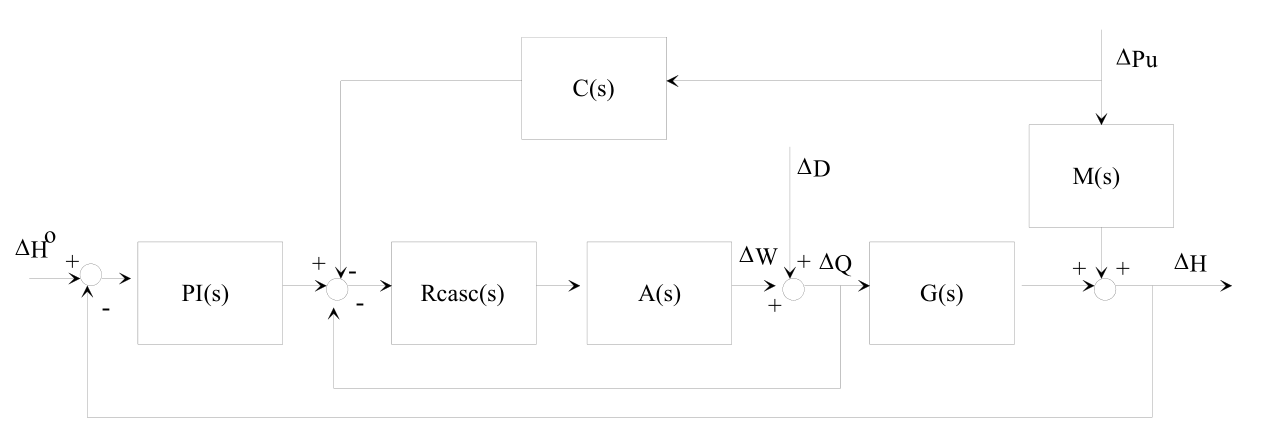

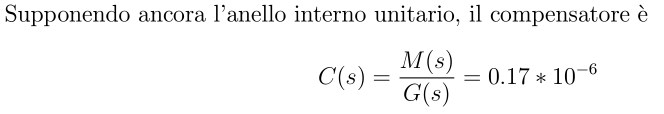

C = S/(rho*g*tau)

C = 1.7788e-07

C = minreal(M/G)


C =
 
  1.779e-07
 
Static gain.

